% none model parameters
tic
x=1;
x1 = 1;

sensitivity=table();
specificity=table();
datestr(now, 'dd/mm/yy-HH:MM')

ans = '13/05/24-12:46'

sensitivity1=table();
specificity1=table();
accuracytb=table();
precision=table();

%rootDir = "C:\Users\bhavana.maradani\Desktop\Feb_6_2023\stoneID_classification";
rootDir = "D:\Script";
%for integra = [1 50 75 150 250 350]
integra = 1

integra = 1

dslocation = fullfile(rootDir, "data", "XL-Spec1/");
datadescription = 'TDP-12'; 
distanceRange = 'ZeroToFour';
[dataAll, dataSummary] = ops.import.readCSV( dslocation, IncludeSubfolders=true);

% Add all folders to path
addpath(genpath(rootDir))
dataAll.Response = dataAll.TargetType;
size(dataAll)

ans =         1875        2058


% consider only current integration time
dataAll(dataAll.IntegrationTimeUsed ~= string(integra) ,:) = [];
currentFilter = dataAll.ResponseRegression >= 0 & dataAll.ResponseRegression < 5;
dataAll = dataAll(currentFilter, :);
size(dataAll)

ans =         1875        2058


data = dataAll;
data.Response(ismember(data.Response, ["Access Sheath 13 15"...
   "Endoscope", "COM","UA", "BEGO"])) = "Non-Tissue";
data.Response(ismember(data.Response, ["Tissue-Calyx", "Tissue-Ureter"])) = "Tissue";


%obj = load('C:\Users\bhavana.maradani\Olympus\LOTR - ML Scripts\Tissue Sense results\TDP-08\TwoToFour\1ExperimentML_Trial1_Model2_Apr062023.mat');
%model = obj.result
%model2 = obj.model2
%cm = CMprediction(model1, dataAll(:, [1:2048, 2050]));
%cm2 = CMprediction(model2, dataAll(:, [1:2048, 2050]));
formatOut = 'yyyymmddTHHMMSS';
CurrentDate=datestr(now,formatOut);
savefigloc='C:\Users\bhavana.maradani\Desktop\temp\';
filePath1 = "C:\Users\bhavana.maradani\Desktop\TissueSense_5sample\Xenon AB off\TS_1XenonABOFF-5AvgZeroToFour05_10_2024_13_08.mat";
result = predictFcn(filePath1, data(:, [1:2048, 2058]));

accuracy = sum(result.("Response") == result.Prediction) / numel(result.("Response"));

f8=figure()
cm=viz.confusionchart( result, "Response", "Prediction", ...
            "Title", "Test Data Accuracy = " + 100*accuracy + "%", ...
            "Normalization", "row-normalized", ...
            "RowSummary","row-normalized","ColumnSummary","column-normalized");

f8 =   Figure (1) with properties:

      Number: 1
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [488 338 560 420]
       Units: 'pixels'

  Show all properties


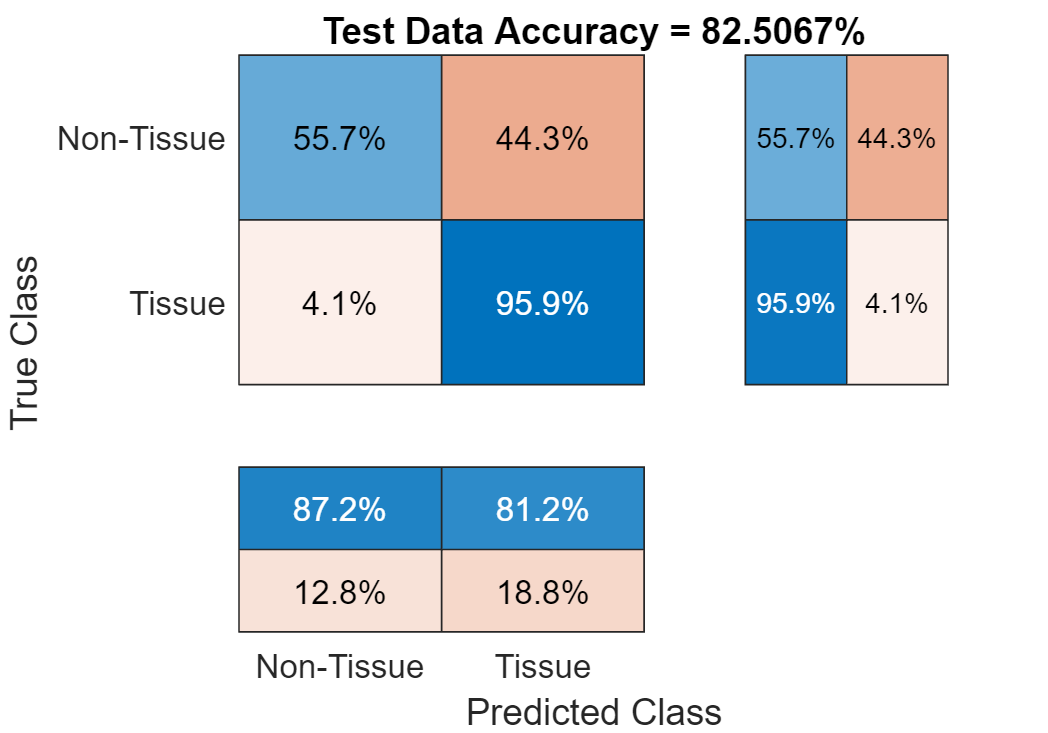

Description = 'Confusion Chart';
savenamefig=strcat(savefigloc,Description,CurrentDate,'.fig');
savenamejpg=strcat(savefigloc,Description,CurrentDate,'.jpg');
f8.Position = [10,10,1000,700];

% saveas(f8,savenamefig);
% saveas(f8,savenamejpg);

beep on
beep
confidence = result.Scores
matrix=cm.NormalizedValues;
labels=string(cm.ClassLabels);
statsmatix= statsOfMeasure(matrix,1);

stats = 9×4 table
          name               classes          macroAVG    microAVG
    ________________    __________________    ________    ________

    "true_positive"      0.5568     0.9592      0.758      0.758  
    "false_positive"     0.0408     0.4432      0.242      0.242  
    "false_negative"     0.4432     0.0408      0.242      0.242  
    "true_negative"      0.9592     0.5568      0.758      0.758  
    "precision"         0.93173    0.68397    0.80785      0.758  
    "sensitivity"        0.5568     0.9592      0.758      0.758  
    "specificity"        0.9592     0.5568      0.758      0.758  
    "accuracy"            0.758      0.758      0.758      0.758  
    "F-measure"         0.69705    0.79853    0.74779      0.758  



if x==1  

sensitivity{x,:}= statsmatix.classes(6,:);
specificity{x,:}= statsmatix.classes(7,:);
sensitivity.Properties.VariableNames =labels;
specificity.Properties.VariableNames =labels;

else 

sensitivity{x,:}= statsmatix.classes(6,:);
specificity{x,:}= statsmatix.classes(7,:);
sensitivity
specificity
end 
x=x+1;
